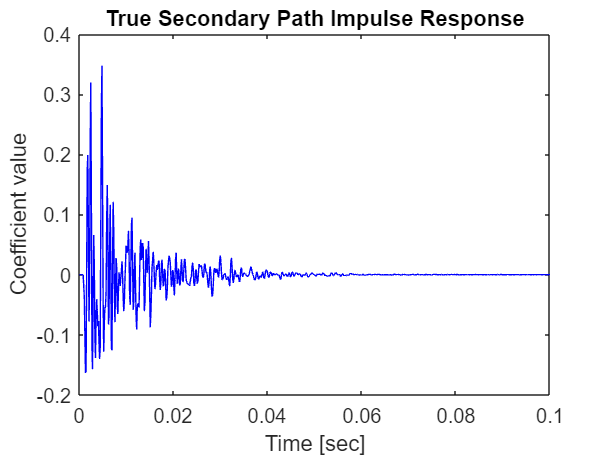

Fs     = 8e3;  % 8 kHz
N      = 800;  % 800 samples@8 kHz = 0.1 seconds
Flow   = 160;  % Lower band-edge: 160 Hz
Fhigh  = 2000; % Upper band-edge: 2000 Hz
delayS = 7;
Ast    = 20;   % 20 dB stopband attenuation
Nfilt  = 8;    % Filter order

% Design bandpass filter to generate bandlimited impulse response
filtSpecs = fdesign.bandpass('N,Fst1,Fst2,Ast',Nfilt,Flow,Fhigh,Ast,Fs);
bandpass = design(filtSpecs,'cheby2','FilterStructure','df2tsos', ...
    'SystemObject',true);

% Filter noise to generate impulse response
secondaryPathCoeffsActual = bandpass([zeros(delayS,1); ...
                       log(0.99*rand(N-delayS,1)+0.01).* ...
                       sign(randn(N-delayS,1)).*exp(-0.01*(1:N-delayS)')]);
secondaryPathCoeffsActual = ...
    secondaryPathCoeffsActual/norm(secondaryPathCoeffsActual);

t = (1:N)/Fs;
plot(t,secondaryPathCoeffsActual,'b');
xlabel('Time [sec]');
ylabel('Coefficient value');
title('True Secondary Path Impulse Response');

ntrS = 30000;
randomSignal = randn(ntrS,1); % Synthetic random signal to be played
secondaryPathGenerator = dsp.FIRFilter('Numerator',secondaryPathCoeffsActual.');
secondaryPathMeasured = secondaryPathGenerator(randomSignal) + ... % random signal propagated through secondary path
    0.01*randn(ntrS,1); % measurement noise at the microphone

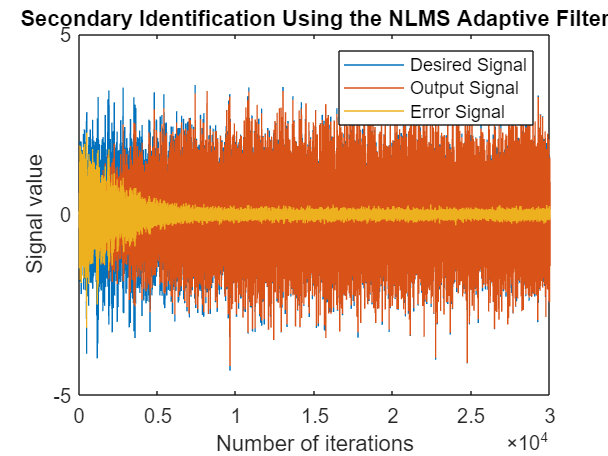

M = 250;
muS = 0.1;
secondaryPathEstimator = dsp.LMSFilter('Method','Normalized LMS','StepSize', muS, ...
    'Length', M);
[yS,eS,SecondaryPathCoeffsEst] = secondaryPathEstimator(randomSignal,secondaryPathMeasured);

n = 1:ntrS;
figure, plot(n,secondaryPathMeasured,n,yS,n,eS);
xlabel('Number of iterations');
ylabel('Signal value');
title('Secondary Identification Using the NLMS Adaptive Filter');
legend('Desired Signal','Output Signal','Error Signal');

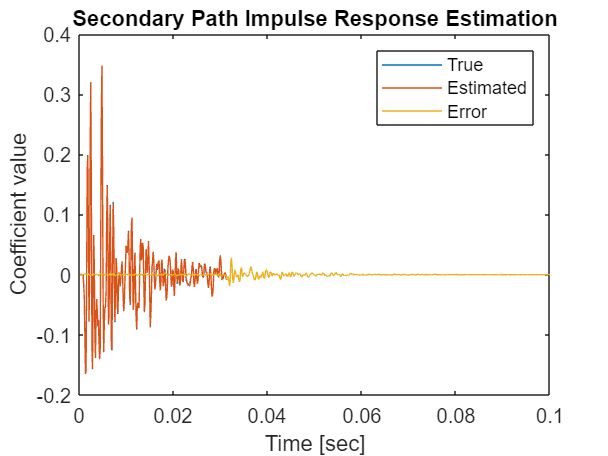

figure, plot(t,secondaryPathCoeffsActual, ...
    t(1:M),SecondaryPathCoeffsEst, ...
    t,[secondaryPathCoeffsActual(1:M)-SecondaryPathCoeffsEst(1:M); secondaryPathCoeffsActual(M+1:N)]);
xlabel('Time [sec]');
ylabel('Coefficient value');
title('Secondary Path Impulse Response Estimation');
legend('True','Estimated','Error');

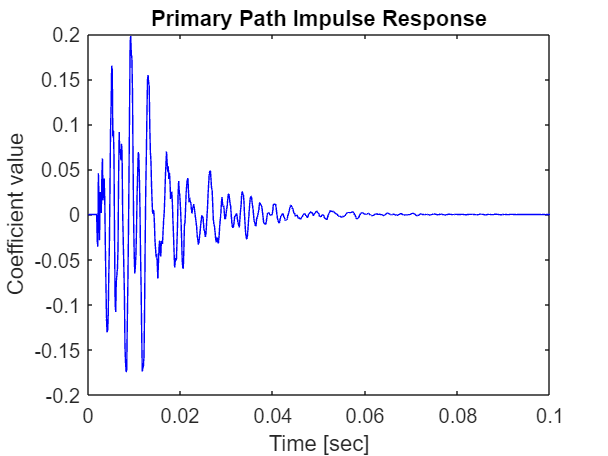

delayW = 15;
Flow   = 200; % Lower band-edge: 200 Hz
Fhigh  = 800; % Upper band-edge: 800 Hz
Ast    = 20;  % 20 dB stopband attenuation
Nfilt  = 10;  % Filter order

% Design bandpass filter to generate bandlimited impulse response
filtSpecs2 = fdesign.bandpass('N,Fst1,Fst2,Ast',Nfilt,Flow,Fhigh,Ast,Fs);
bandpass2 = design(filtSpecs2,'cheby2','FilterStructure','df2tsos', ...
    'SystemObject',true);

% Filter noise to generate impulse response
primaryPathCoeffs = bandpass2([zeros(delayW,1); log(0.99*rand(N-delayW,1)+0.01).* ...
    sign(randn(N-delayW,1)).*exp(-0.01*(1:N-delayW)')]);
primaryPathCoeffs = primaryPathCoeffs/norm(primaryPathCoeffs);

figure, plot(t,primaryPathCoeffs,'b');
xlabel('Time [sec]');
ylabel('Coefficient value');
title('Primary Path Impulse Response');

% FIR Filter to be used to model primary propagation path
primaryPathGenerator = dsp.FIRFilter('Numerator',primaryPathCoeffs.');

% Filtered-X LMS adaptive filter to control the noise
L = 350;
muW = 0.0001;
noiseController = dsp.FilteredXLMSFilter('Length',L,'StepSize',muW, ...
    'SecondaryPathCoefficients',SecondaryPathCoeffsEst);

% Sine wave generator to synthetically create the noise
A = [.01 .01 .02 .2 .3 .4 .3 .2 .1 .07 .02 .01];
La = length(A);
F0 = 60;
k = 1:La;
F = F0*k;
phase = rand(1,La); % Random initial phase
sine = audioOscillator('NumTones', La, 'Amplitude',A,'Frequency',F, ...
    'PhaseOffset',phase,'SamplesPerFrame',512,'SampleRate',Fs);

% Audio player to play noise before and after cancellation
player = audioDeviceWriter('SampleRate',Fs);

% Spectrum analyzer to show original and attenuated noise
scope = spectrumAnalyzer('SampleRate',Fs, ...
    'PlotAsTwoSidedSpectrum',false, ...
    'ShowLegend',true, ...
    'ChannelNames', {'Original noisy signal', 'Attenuated noise'});

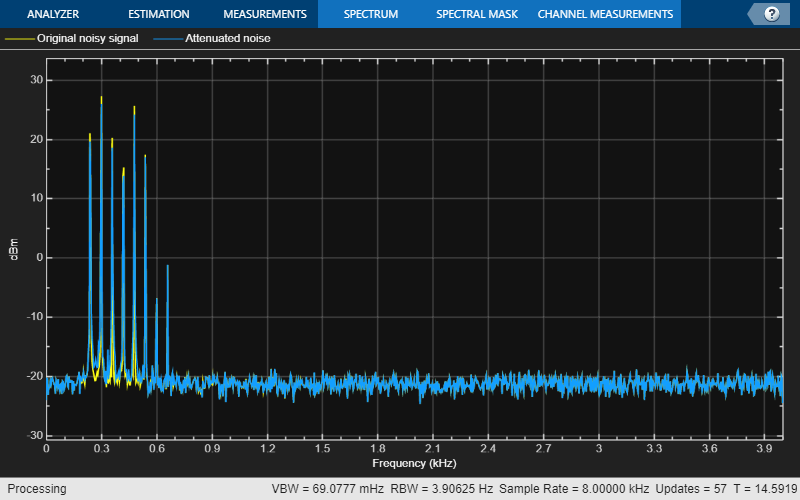

for m = 1:400
    % Generate synthetic noise by adding sine waves with random phase
    x = sine();
    d = primaryPathGenerator(x) + ...  % Propagate noise through primary path
        0.1*randn(size(x)); % Add measurement noise
    if m <= 200
        % No noise control for first 200 iterations
        e = d;
    else
        % Enable active noise control after 200 iterations
        xhat = x + 0.1*randn(size(x));
        [y,e] = noiseController(xhat,d);
    end
    player(e);     % Play noise signal
    scope([d,e]); % Show spectrum of original (Channel 1)
                     % and attenuated noise (Channel 2)
end

release(player); % Release audio device
release(scope); % Release spectrum analyzer